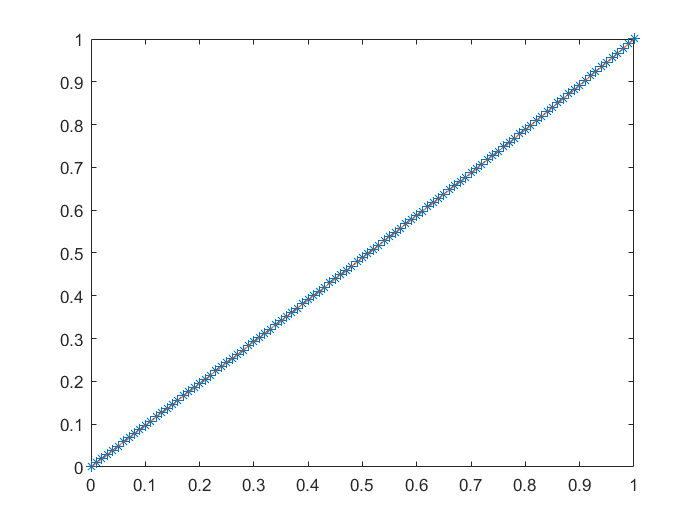

% 没做完
clc,clear,close all
xn = 1;x0 = 0;
n = 100;
h = (xn-x0)/n;
x = x0:h:(xn-h);
A0 = [1,zeros(1,n)];
A1 = [diag(ones(1,n-1)) , zeros(n-1,2)];
A2 = [zeros(n-1,1),diag(ones(1,n-1))*(h^2-2) , zeros(n-1,1)];
A3 = [zeros(n-1,2),diag(ones(1,n-1))];
A4 = [zeros(1,n),1];
A = [A0;A1+A2+A3;A4];
b = [h^2*tan(x');1];
y = A\b;
plot(x0:h:xn,y,'*')


syms y(t)
cond = [y(0) == 0,y(1)==1];
f = dsolve(diff(y,t,2) + y== tan(t),cond);
f = matlabFunction(f);
x = x0:h:xn;
hold on
plot(x,f(x))